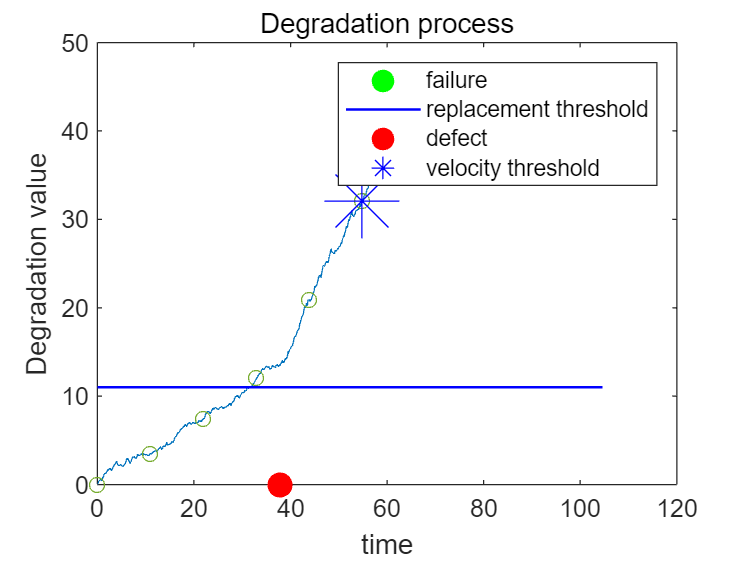

clear all 
clc
% Parameter set
mu1=0.4;
sigma1=0.3;
mu2=1.3;
sigma2=0.5;%QREI parameter不符合相应情况，需要更改

beta=0.3;
alpha=0.2;

Lf=45;
Lp=11;
Lv=1;

%% Operation cost
cia=100;
cib=100;
cf=20000;
cp=2000;
%% Parameter no.1
tau=11;
d1=20; % delay time of velocity
d2=15; % delay time of defection
d0=1;

% Creation of defect point
Expectation_def=30; %偏移的正态分布
sigma_def=5.1;
%Z=fix(randn()*sigma_def+Expectation_def);% 生成正态分布型Z

% 设定形状参数 k（Weibull 分布常见形状参数为 2 接近正态分布）
k = 2;
lambda = Expectation_def / gamma(1 + 1/k); % 计算对应的尺度参数

% 生成一个 Weibull 分布的随机数
U = rand(); % 生成一个 (0,1) 之间的均匀随机数
Z = fix(lambda * (-log(U))^(1/k)); % 通过逆变换法生成 Weibull 分布随机数
%weilbull distribustion
%k=3.7;
%lambda=16.2;
%U=rand();
%Z=fix(lambda * (-log(1 - U))^(1/k));
T_inf=30;

% Generation of Wiener process
step=0.1;
[t_1 X_1]=wiener(mu1,sigma1,Z,Z/step);
[t_2 X_2]=wiener(mu2,sigma2,T_inf,T_inf/step);
X_2=X_1(end)+X_2;
t_2=t_1(end)+t_2;

t=[t_1 t_2];
X=[X_1 X_2];
%% Visulization of the degradation process
plot(t,X)
xlabel("time")
ylabel("Degradation value")
title("Degradation process")
hold on

% Determination of the characteristic time based on thresholds
Tf=t(find(X>Lf,1)); % failure appear
Tp=t(find(X>Lp,1)); % threshold appear
Z; % Defect appear
%% visulization
pf=plot(Tf,Lf,'.','color','g','MarkerSize',30);
pp=plot([0 Z+Tf],[Lp Lp],'b-','LineWidth',1);
pd=plot(Z,0,'.','color','r','MarkerSize',30);

%% determination of the degradation velocity based on inspection
%% 计算速率向量，将得到的新矩阵与Lv进行比较,精确版本&高效版本
%!!!!需要根据tau来计算
tins=t(mod(t,tau)==0); % inspection time
Xins=X(1+tins/step); % perfect degradation inspection

scanning_length=1;
dX=[Xins 0]-[0 Xins]; % point 1-point 0 
dt=[tins 0]-[0 tins]; % represents the slope beteween this point and the point before
Vall=dX./dt;
Tv=tins(find(Vall>Lv,1)); % find Tv from the inspection interval
Xv=Xins(find(Vall>Lv,1));

% Visulization
scatter(tins,Xins)
pv=plot(Tv,Xv,'*','color','b','MarkerSize',30);
legend([pf,pp,pd,pv],'failure','replacement threshold','defect',"velocity threshold")
hold off;



% Maintenance policy
% Complexity O（N）
i=0;
T_max=max(t);
C=0;
T=0;
f=0; %determine if Tmax is changed
while (T<T_max)
    i=i+1;
    C=C+cia;
    velocity=(X((T+tau+1)/step)-X((T+1)/step))/tau;

    T=T+tau;
    if T>=Tf %直接失败的惩罚
        T_max=Tf;
        C=C+cf;
        break
    elseif velocity>Lv
        if T<Z
            disp("false");
        end
        T_max=T+d1;
        % delay time model (TBM)
        T=T_max;
        if T>=Tf
            C=C+cf;
        end
        break
    elseif T>Tp
        T_max=T+d0;
        % delay time model (TBM)
        T=T_max;
        if T>=Tf
            C=C+cf;
        end
        break
    end

    C=C+cib;
    if T>Z % FN
        b=rand(); %generate random number between 0 1
        if b>beta %defect detected
            T_max=T+d2;
            % delay time model (TBM)
            T=T_max;
            if T>=Tf
                C=C+cf;
            end
            break
        end
    elseif velocity<Lv   % FP 双重检验
        a=rand();
        if a<alpha %FP
            T_max=T+d2;
            % delay time model (TBM)
            T=T_max;
            if T>=Tf
                C=C+cf;
            end
            break
        end
    end

end
C=C+cp; %return

if T>=Tf % 排除冗余项
    C=C-cp;
    %elseif T>Tp
    %C=C-cp;
end
    


C/T

ans = 73.5294

T

T = 34


%% Detection of the degradation velocity based on inspection
%% 对每个点附近的两点，进行最小二乘拟合，将得到的新矩阵与Lv进行比较


